clear all
close all
clc
format long

%%%%%%%%%%%%%%%%%%%%%%%%%'explicit upwind method'%%%%%%%%%%%%%%%%%%%%%%%%

disp '===========N=100,M=100============='

===========N=100,M=100=============


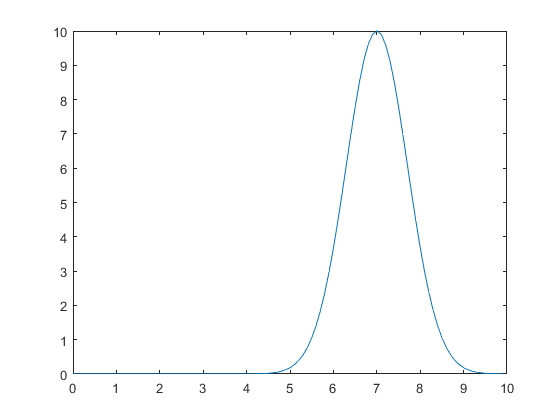

L=10;
N=100;
dx=L/N;
x=[0:dx:L-dx]';
T=2;
M=100;
% M=50;
% M=10;
dt=T/M;
t=[0:dt:T];
a=1;

c0=@(x) 10*exp(-((x-L/2)./(L/10)).^2);
y=@(x,t) c0(x-a*t);

y_exact=y(x,T);

figure(1)
plot(x,y_exact)

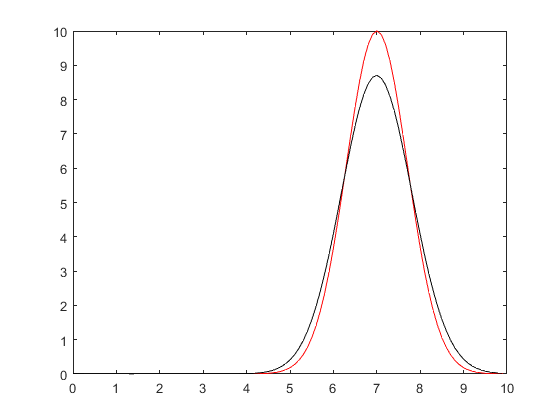


landa=a*(dt/dx);
A1=(1-landa)*ones(1,length(x));
A2=(landa)*ones(1,length(x)-1);
A=diag(A1,0)+diag(A2,-1);
A(1,end)=landa;

y0=c0(x);
c_old=y0;

for i=1:length(t)-1
    c_new=A*c_old;
    c_old=c_new;
end

figure(2)
plot(x,y_exact,'r',x,c_new,'k')


%%% after plotting y_exact and c_new, it can be seen that these two graphs 
%%% are not concide match correctly, it is because of numerical diffusion
%%% not physical diffusion. with getting larg N , two plot match correctly.
%%% with change M=50 nothing happens and with M=10 , because of the amount
%%% of lambda get larger than 1 , therefore the approximation of cext with
%%% cnew is wrong, and the chart blows up

rel_err_inf=norm(abs(y_exact-c_new),inf)./norm(abs(y_exact),inf)

rel_err_inf =    0.129653684186997


rel_err_2=sqrt(dx)*norm(abs(y_exact-c_new))./norm(abs(y_exact))

rel_err_2 =    0.036680709754616



disp '===========N=200,M=200============='

===========N=200,M=200=============


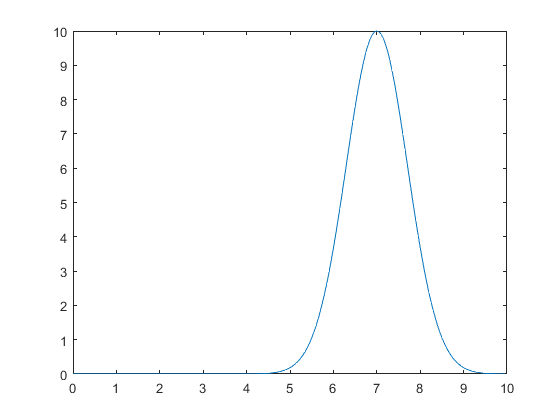

L1=10;
N1=200;
dx1=L1/N1;
x1=[0:dx1:L1-dx1]';
T1=2;
M1=200;
% M=50;
% M=10;
dt1=T1/M1;
t1=[0:dt1:T1];
a1=1;

c01=@(x) 10*exp(-((x-L1/2)./(L1/10)).^2);
y1=@(x,t) c01(x-a1*t);

y_exact1=y1(x1,T1);

figure(3)
plot(x1,y_exact1)

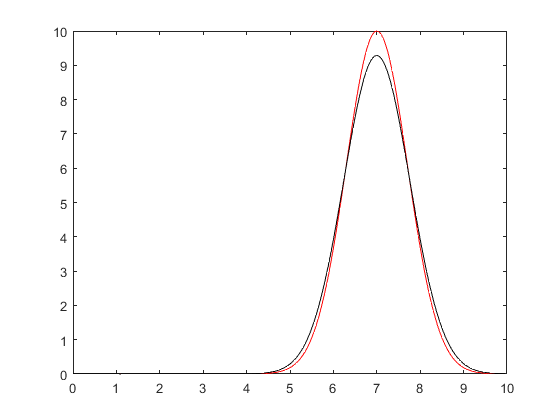


landa1=a1*(dt1/dx1);
A3=(1-landa1)*ones(1,length(x1));
A4=(landa1)*ones(1,length(x1)-1);
A1=diag(A3,0)+diag(A4,-1);
A1(1,end)=landa1;

y01=c01(x1);
c_old1=y01;

for i=1:length(t1)-1
    c_new1=A1*c_old1;
    c_old1=c_new1;
end

figure(4)
plot(x1,y_exact1,'r',x1,c_new1,'k')



rel_err_inf1=norm(abs(y_exact1-c_new1),inf)./norm(abs(y_exact1),inf)

rel_err_inf1 =    0.071526239247728


rel_err_21=sqrt(dx1)*norm(abs(y_exact1-c_new1))./norm(abs(y_exact1))

rel_err_21 =    0.014102065758361



p_emp1=-log2(rel_err_inf1/rel_err_inf)

p_emp1 =    0.858118708124946


p_emp2=-log2(rel_err_21/rel_err_2)

p_emp2 =    1.379115041625741



% %%%%%%%%%%%%%%%%%%%%%%%%%'lax-wandroff method'%%%%%%%%%%%%%%%%%%%%%%%%
% 
% disp '===========N=100,M=100============='
% L=10;
% N=100;
% dx=L/N;
% x=[0:dx:L-dx]';
% T=2;
% M=100;
% % M=50;
% % M=10;
% dt=T/M;
% t=[0:dt:T];
% a=1;
% 
% c0=@(x) 10*exp(-((x-L/2)./(L/10)).^2);
% y=@(x,t) c0(x-a*t);
% 
% y_exact=y(x,T);
% 
% figure(1)
% plot(x,y_exact)
% 
% landa=a*(dt/dx);
% A1=(1-landa^2)*ones(1,length(x));
% A2=((landa^2+landa)/2)*ones(1,length(x)-1);
% A3=((landa^2-landa)/2)*ones(1,length(x)-1);
% A=diag(A1,0)+diag(A2,-1)+diag(A3,1);
% 
% 
% y0=c0(x);
% c_old=y0;
% 
% for i=1:length(t)-1
%     c_new=A*c_old;
%     c_old=c_new;
% end
% 
% figure(2)
% plot(x,y_exact,'r',x,c_new,'k')
% 
% rel_err_inf=norm(abs(y_exact-c_new),inf)./norm(abs(y_exact),inf)
% rel_err_2=sqrt(dx)*norm(abs(y_exact-c_new))./norm(abs(y_exact))
% 
% disp '===========N=200,M=200============='
% L1=10;
% N1=200;
% dx1=L1/N1;
% x1=[0:dx1:L1-dx1]';
% T1=2;
% M1=200;
% % M=50;
% % M=10;
% dt1=T1/M1;
% t1=[0:dt1:T1];
% a1=1;
% 
% c01=@(x) 10*exp(-((x-L1/2)./(L1/10)).^2);
% y1=@(x,t) c01(x-a1*t);
% 
% y_exact1=y1(x1,T1);
% 
% figure(3)
% plot(x1,y_exact1)
% 
% landa1=a1*(dt1/dx1);
% A4=(1-landa^2)*ones(1,length(x1));
% A5=((landa^2+landa)/2)*ones(1,length(x1)-1);
% A6=((landa^2-landa)/2)*ones(1,length(x1)-1);
% A11=diag(A4,0)+diag(A5,-1)+diag(A6,1);
% 
% y01=c01(x1);
% c_old1=y01;
% 
% for i=1:length(t1)-1
%     c_new1=A11*c_old1;
%     c_old1=c_new1;
% end
% 
% figure(4)
% plot(x1,y_exact1,'r',x1,c_new1,'k')
% 
% 
% rel_err_inf1=norm(abs(y_exact1-c_new1),inf)./norm(abs(y_exact1),inf)
% rel_err_21=sqrt(dx1)*norm(abs(y_exact1-c_new1))./norm(abs(y_exact1))
% 
% p_emp1=-log2(rel_err_inf1/rel_err_inf)
% p_emp2=-log2(rel_err_21/rel_err_2)


